#  **3D image processing** **using 3D-DCT**

This example shows how to process an colour image using the three-dimensional discrete cosine transferm (3D DCT).

Read an image into the workspace, then convert the image to double (after that  to Single-precision floating).



[X,map] = imread('corn.tif');
if ~isempty(map)
    Im = ind2rgb(X,map);
end


Perform a 3D DCT of the colour image using the `Discrete_Transform_3D` function. Working only with Single-precision

J = Discrete_Transform_3D(single(Im), 'cosine', 'direct', 'four', 'full');

Reconstruct the image using the inverse 3D DCT function `Discrete_Transform_3D`.

K = Discrete_Transform_3D(single(J), 'cosine', 'inverse', 'four', 'full');

Display the original colour image alongside the processed image.

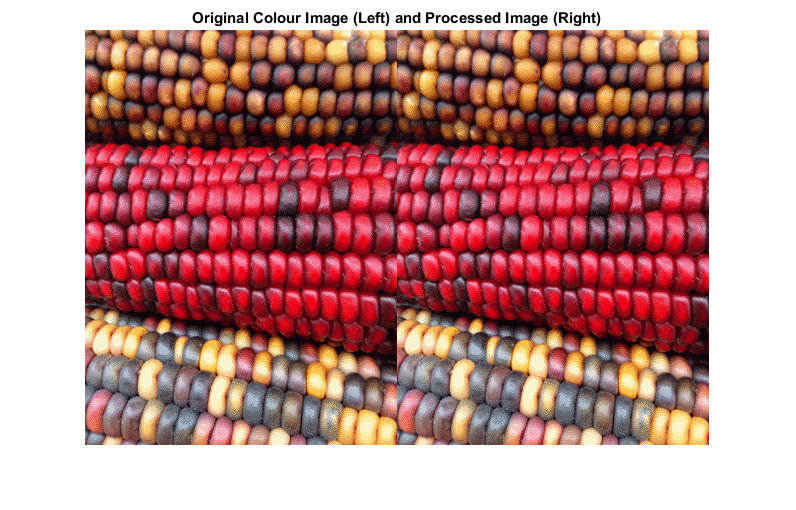



figure
imshowpair(Im,K,'montage')
title('Original Colour Image (Left) and Processed Image (Right)');